%% =========================================================================
% Demo: Main analysis pipeline for SVR-based multivariate prediction
%
% This tutorial demonstrates a complete analysis workflow using the
% MVPA Toolkit. The simulated dataset contains:
%
%   • 10 subjects
%   • 4 observations per subject
%   • Group-based cross-validation
%   • Known ground-truth activation pattern
%   • Correlated feature noise
%
% The purpose of this demo is to illustrate:
%
%   (1) SVR model training
%   (2) Cross-validated prediction
%   (3) Statistical evaluation of prediction performance
%   (4) Statistical inference on feature importance
%   (5) Haufe transform for interpreting predictive models
%
% -------------------------------------------------------------------------
%
% Analysis workflow
%
%   Simulated data
%          │
%          ▼
%   Group cross-validation
%          │
%          ▼
%      Train SVR model
%          │
%          ▼
%   Cross-validated prediction
%          │
%          ├────────► Prediction accuracy (permutation)
%          │            • Correlation
%          │            • RMSE
%          │
%          └────────► Feature importance (bootstrap)
%                       • Predictive weights
%                       • Haufe activation patterns
%
% -------------------------------------------------------------------------
%
% The simulated data were generated using the encoding model
%
%       X = sA' + noise
%
% where
%
%       X : feature matrix
%       s : latent signal
%       A : ground-truth activation pattern
%
% Consequently, A represents the "true" feature importance.
%
% The decoder weights learned by SVR are optimized for prediction rather
% than interpretation. When features are correlated, predictive weights
% often differ substantially from the underlying activation pattern.
%
% The Haufe transform converts predictive weights into activation patterns,
% making them directly comparable to the true encoding model.
%
% Therefore, this simulation provides a quantitative demonstration that
%
%       Ground Truth
%            ↑
%      Haufe Pattern
%            ↑
%     Predictive Weight
%
% Haufe patterns recover the underlying activation pattern more faithfully
% than predictive weights.
%
% =========================================================================

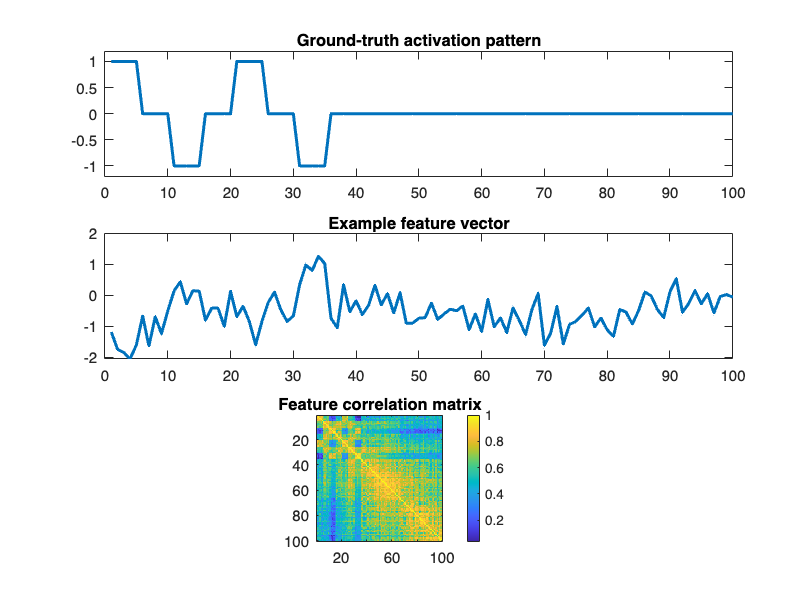


addpath(genpath("MVPA_toolkit"));

%% =========================================================================
% Visualize simulated data
% ========================================================================
clear;clc
load("Demo/Data/demo_data.mat")
figure

subplot(311)
plot(A,'LineWidth',2)
ylim([-1.2 1.2])
title('Ground-truth activation pattern')

subplot(312)
plot(x(1,:),'LineWidth',2)
title('Example feature vector')

subplot(313)
imagesc(corr(x))
axis square
colorbar
title('Feature correlation matrix')


%% =========================================================================
% Cross-validation settings
% =========================================================================

cv = [5 5];

param = [];

param.scale      = 1;
param.covariates = 0;
param.po         = 0;

param.progress   = 1;
param.text       = 1;
param.savefolds  = 1;

param.groupCV    = groupCV;

%% =========================================================================
% Train SVR model
% =========================================================================

[out,log] = mat_cv(x,y,[],'svr',cv,param);

--------- Cross Validation ---------
Model training based on Matlab default parameters.
--------->>> Repetition: 1; Folds: 1
The accuracy in current fold: 0.98735
-------------------------------------
Model training based on Matlab default parameters.
--------->>> Repetition: 1; Folds: 2
The accuracy in current fold: 0.99584
-------------------------------------
Model training based on Matlab default parameters.
--------->>> Repetition: 1; Folds: 3
The accuracy in current fold: 0.98043
-------------------------------------
Model training based on Matlab default parameters.
--------->>> Repetition: 1; Folds: 4
The accuracy in current fold: 0.99557
-------------------------------------
Model training based on Matlab default parameters.
--------->>> Repetition: 1; Folds: 5
The accuracy in current fold: 0.96576
-------------------------------------
Model training based on Matlab default parameters.
--------->>> Repetition: 2; Folds: 1
The accuracy in current fold: 0.98117
-----------------


%% =========================================================================
% Model evaluation
% =========================================================================

out = mat_report_correlation(out,log);

Description:
The 5 folds cross-validation (CV) has been conducted for 5 times.

---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
Overall model evaluation:
The overall prediction-outcome correlation coefficient (r) is 0.974 (averaged across repetations); the bootstrapped 95% confidence interval (CI) is [0.971, 0.978]; the standard error (SE) is 0.00.

The overall prediction-outcome explained variance score (EVS, r2) is 0.947 (averaged across repetations); the bootstrapped 95% confidence interval (CI) is [0.942, 0.956]; the standard error (SE) is 0.00.

The overall prediction-outcome mean absolute error (MAE) is 0.212 (averaged across repetations); the bootstrapped 95% confidence interval (CI) is [0.197, 0.225]; the standard error (SE) is 0.01.

The overall prediction-outcome root mean squared error (R


%% =========================================================================
% Permutation test
% =========================================================================

out = mat_permutation(...
    x,y,[],log,out,...
    'N',1000);

%% =========================================================================
% Bootstrap predictive weights and Haufe transform
% =========================================================================

[out,bootweight,haufeweight] = mat_bootstrap_new(...
    x,y,[],...
    log,out,...
    'N',1000,...
    'opt_parameter',1,...
    'parallel',...
    'Haufe',3,...
    'parpool',5);

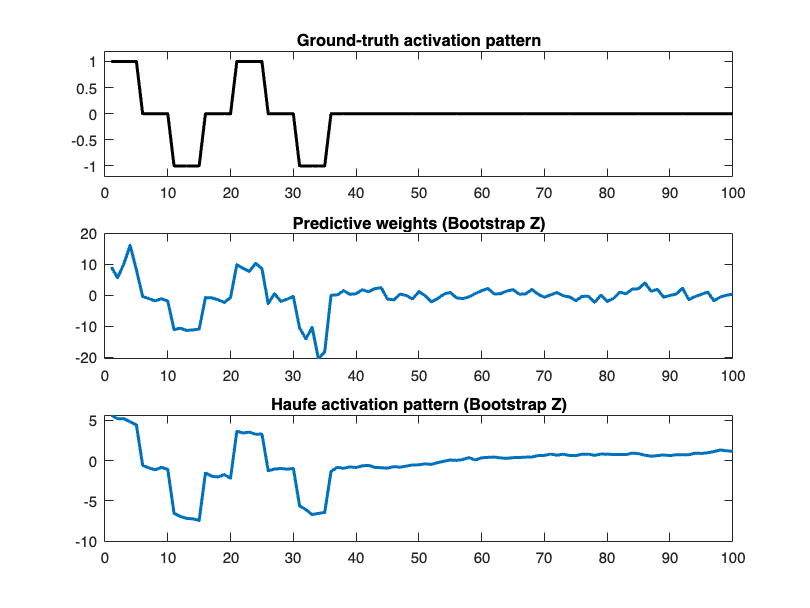

%% =========================================================================
% Compare ground truth, predictive weights and Haufe patterns
% =========================================================================

figure

subplot(311)
plot(A,'k','LineWidth',2)
ylim([-1.2 1.2])
title('Ground-truth activation pattern')

subplot(312)
plot(out.boot_Z,'LineWidth',2)
title('Predictive weights (Bootstrap Z)')

subplot(313)
plot(out.boot_haufe_Z,'LineWidth',2)
title('Haufe activation pattern (Bootstrap Z)')